%load data into X and y
load('ex3data1.mat');

There are 5000 training examples in the dataset, where each example is a 20 pixel by 20 pixel grayscale image of the digit . This 20 by 20 pixels is unrolled into a 400 dimensional vector.Thus X is a 5000 by 400 matrix

## Visualization

The code randomly selects 100 examples from the training examples

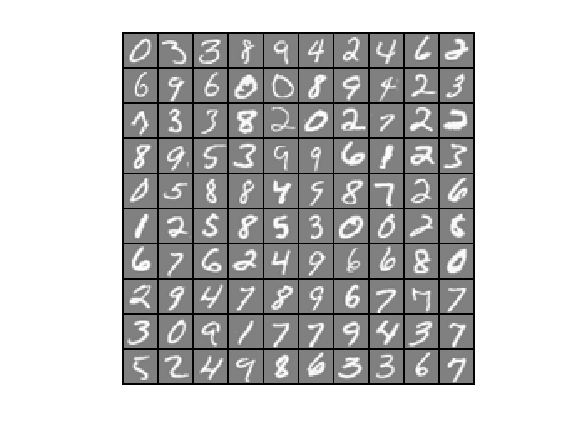

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);

displayData(sel);

## 1.Regularized Logistics Regression

We will be using multiple one vs all logistic regression models to build a multi-class classifier. Since there are 10 classes , we will train 10 separate logistic classifiers. 

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

fprintf('Cost: %f | Expected cost: 2.534819\n',J);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('Gradients:\n'); fprintf('%f\n',grad);

Gradients:
0.146561
-0.548558
0.724722
1.398003


fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

## 1.a.One-vs-all Classification 

We will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the 10 classes in our dataset

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

Iteration     1 | Cost: 2.802128e-01
Iteration     2 | Cost: 9.454389e-02
Iteration     3 | Cost: 5.704641e-02
Iteration     4 | Cost: 4.688190e-02
Iteration     5 | Cost: 3.759021e-02
Iteration     6 | Cost: 3.522008e-02
Iteration     7 | Cost: 3.234531e-02
Iteration     8 | Cost: 3.145034e-02
Iteration     9 | Cost: 3.008919e-02
Iteration    10 | Cost: 2.994639e-02
Iteration    11 | Cost: 2.678528e-02
Iteration    12 | Cost: 2.660323e-02
Iteration    13 | Cost: 2.493301e-02
Iteration    14 | Cost: 2.475211e-02
Iteration    15 | Cost: 2.318421e-02
Iteration    16 | Cost: 2.287050e-02
Iteration    17 | Cost: 2.160258e-02
Iteration    18 | Cost: 2.120371e-02
Iteration    19 | Cost: 2.064125e-02
Iteration    20 | Cost: 2.055695e-02
Iteration    21 | Cost: 2.045466e-02
Iteration    22 | Cost: 2.029177e-02
Iteration    23 | Cost: 2.005296e-02
Iteration    24 | Cost: 1.995949e-02
Iteration    25 | Cost: 1.982849e-02
Iteration    26 | Cost: 1.975129e-02
Iteration    27 | Cost: 1.897815e-02
I

## 1.b.One-vs-all Prediction

The one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 95.000000


## 2.Neural Networks

Logistic regression being a linear classifier cannot implement complex functions. One can add more features like polynomial features to it but its training becomes expensive .

Our model is a three layered neural network containing one input, one hidden and one output layer.

The parameters $(\Theta^{(1)},\Theta^{(2)})$are already provided.

% Load the weights into variables Theta1 and Theta2
load('ex4weights.mat');

### 2.a.Feedforward and regularized cost function

input_layer_size  = 400;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 10;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 0.383770

## 3.Backpropagation

We will implement the backpropagation algorithm to compute the gradient for the neural network cost function.

### 3.a. Sigmoid gradient

We will first implement the sigmoid gradient function. The gradient for the sigmoid function can be computed as


$$g'(z)=\frac{d}{dz}g(z) = g(z)(1-g(z))$$


where


$$\mathrm{sigmoid}(z)=g(z)=\frac{1}{1+e^{-z}}$$


### 3.b.Random Initialization

When training neural networks, it is important to randomly initialize the parameters for symmetry breaking. One effective strategy for random initialization is to randomly select values for $\Theta^{(l)}$ uniformly in the range $[-\epsilon_{int},\epsilon_{init}]$. You should use $\epsilon_{init} = 0.12$*. This range of values ensures that the parameters are kept small and makes the learning more efficient.

initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];

### 3.c. Backpropagation

Given a training example $(x^{(t)}, y^{(t)})$, we will first run a 'forward pass' to compute all the activations throughout the network, including the output value of the hypothesis $h_\Theta(x)$. Then, for each node $j$ in layer $l$, we would like to compute an 'error term' $\delta^{(l)}_j$ that measures how much that node was 'responsible' for any errors in our output.

### 3.d. Gradient checking

Suppose we have a function $f_i(\theta)$ that purportedly computes $\frac{\partial}{\partial\theta_i}J(\theta)$; we'd like to check if $f_i$ is outputting correct derivative values.


$$\textrm{Let}\;\theta^{i+} =\theta +\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack \;\textrm{and}\;\theta^{i-} =\theta -\left\lbrack \begin{array}{c}
0\\
0\\
\vdots \\
\epsilon \\
\vdots \\
0
\end{array}\right\rbrack$$


    So, $\theta^{(i+)}$ is the same as $\theta$, except its $i$-th element has been incremented by $\epsilon$. Similarly, $\theta^{(i-)}$is the corresponding vector with the $i$-th element decreased by $\epsilon$. We can now numerically verify $f_i(\theta)$'s correctness by checking, for each $i$, that:


$$f_i(\theta) \approx \frac{J(\theta^{(i+)})-J(\theta^{(i-)})}{2\epsilon}$$


The degree to which these two values should approximate each other will depend on the details of $J$. But assuming $\epsilon= 10^{-4}$, we'll usually find that the left- and right-hand sides of the above will agree to at least 4 signicant digits (and often many more). 

   The code below will run the provided function `checkNNGradients.m` which will create a small neural network and dataset that will be used for checking your gradients. If your backpropagation implementation is correct, you should see a relative dierence that is less than 1e-9.

checkNNGradients;

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

### 2.5 Regularized neural networks

To account for regularization, we can add this as an additional term after computing the gradients using backpropagation. After we have computed $\Delta^{(l)}_{ij}
$ using backpropagation, we should add regularization using


$$\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} \text{  for  } j = 0,\\
\frac{\partial}{\partial\Theta^{(l)}_{ij}} J(\Theta)= D^{(l)}_{ij}= \frac{1}{m}\Delta^{(l)}_{ij} +\frac{\lambda}{m}\Theta^{(l)}_{ij} \text{  for  } j \geq 1$$


Note that we should *not* be regularizing the first column of $\Theta^{(l)}$ which is used for the bias term. Furthermore, in the parameters $\Theta^{(l)}_{ij}$, $i$ is indexed starting from 1, and $j$ is indexed starting from 0. Thus,


$$\Theta^{\left(l\right)} =\left\lbrack \begin{array}{ccc}
\Theta_{1,0}^{\left(l\right)}  & \Theta_{1,1}^{\left(l\right)}  & \cdots \\
\Theta_{2,0}^{\left(l\right)}  & \Theta_{2,1}^{\left(l\right)}  & \;\\
\vdots  & \; & \ddots 
\end{array}\right\rbrack$$


Somewhat confusingly, indexing in MATLAB starts from 1 (for both $i$ and $j$), thus `Theta1(2, 1)` actually corresponds to $\Theta^{(l)}_{2,0}$ (i.e., the entry in the second row, first column of the matrix $\Theta^{(1)}$ shown above)

%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be

% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

Cost at (fixed) debugging parameters (w/ lambda = 3): 0.576051